# Eksamen 2019 efterår

clc; clear;

CP = py.importlib.import_module("CoolProp.CoolProp");


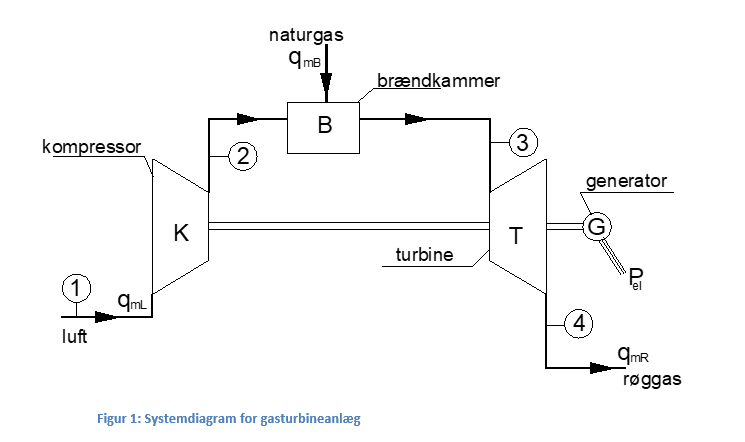

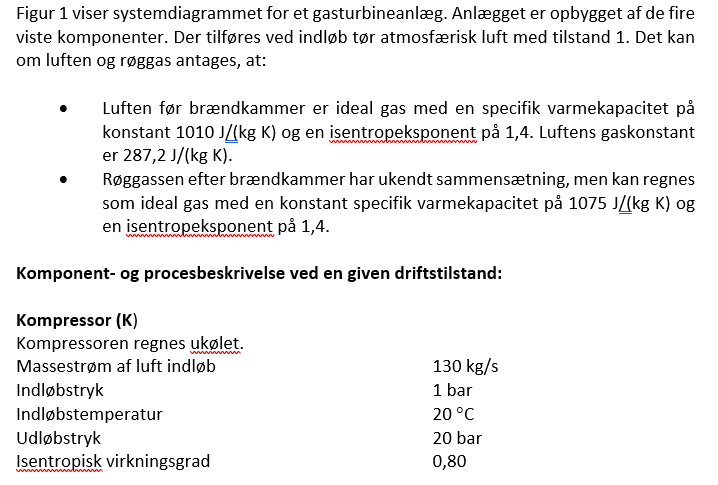

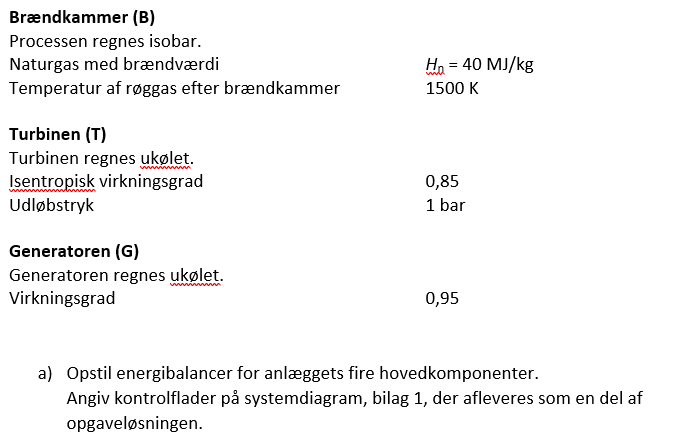

Kontrolflade 1 er kompressoren


$$qmr\cdot(h1-h2) - \Phi_K = 0\\
\Phi_B = qmr\cdot(h2-h3) + qm_b\cdot H_n\\
\Phi_T = qmr\cdot(h3-h4)- \Phi_K - P_G\\
P_G - P_{el} - \phi_{tab} = 0\\
\phi_{tab} = P_G - P_el\\
P_{el} = \eta_{gen}\cdot P_G$$


% Enheder
bar = 101325;
t0 = 273.15;

% Data fra opgaven
kap = 1.4;
cp_luft = 1010;
cp_gas = 1075;
gas_kon = 287.2;
qm_luft = 130;

% Data over kompressoren
t1 = 20 + t0;
p1 = 1*bar;
p2 = 20*bar;
eta_komp = 0.8;
eta_turbine = 0.85;

% Temperatur 2
T2s = nan;
T2s = T2s_UdFraEksponent(T2s, t1, p1, p2, kap)

Energiligningen opstilles:


$$eq = T_{\mathrm{is}}=T_{\mathrm{im1}}\,{\left(\frac{p_{i}}{p_{\mathrm{im1}}}\right)}^{\frac{\kappa -1}{\kappa }}$$

---------------------------------------------------
Der løses for: T_is


$$sol = T_{\mathrm{im1}}\,{\left(\frac{p_{i}}{p_{\mathrm{im1}}}\right)}^{\frac{\kappa -1}{\kappa }}$$

---------------------------------------------------
Resultat og brugte værdier ses i nedenstående skema
           Variabel            Størrelse     Enhed
    _______________________    __________    _____

    "Isentropisk temp. T2s"         689.9    "K"  
    "t1"                            293.2    "K"  
    "p1"                       1.0132e+05    "Pa" 
    "p2"                       2.0265e+06    "Pa" 
    "Isentrop eksponent"              1.4    "-"  



$$T2s = 689.9$$

T2s_celsius = round(T2s - t0,3)

$$T2s\_celsius = 416.792$$


syms t_2
t2 = solve(eta_komp == (T2s - t1)/(t_2-t1), t_2)

$$t2 = 789.14033984355628490447998046875$$

t2_celsius = round(t2-t0,3)

$$t2\_celsius = 515.99$$



% Tryk 3
p3 = p2;
t3 = 1500;
t3_celsius = vpa(t3-t0,4)

$$t3\_celsius = 1227.0$$


% tryk 4
p4 = p1;
t4s = nan;

t4s = T2s_UdFraEksponent(t4s,t3, p3, p4, kap)

Energiligningen opstilles:


$$eq = T_{\mathrm{is}}=T_{\mathrm{im1}}\,{\left(\frac{p_{i}}{p_{\mathrm{im1}}}\right)}^{\frac{\kappa -1}{\kappa }}$$

---------------------------------------------------
Der løses for: T_is


$$sol = T_{\mathrm{im1}}\,{\left(\frac{p_{i}}{p_{\mathrm{im1}}}\right)}^{\frac{\kappa -1}{\kappa }}$$

---------------------------------------------------
Resultat og brugte værdier ses i nedenstående skema
           Variabel            Størrelse     Enhed
    _______________________    __________    _____

    "Isentropisk temp. t4s"         637.3    "K"  
    "t3"                             1500    "K"  
    "p3"                       2.0265e+06    "Pa" 
    "p4"                       1.0132e+05    "Pa" 
    "Isentrop eksponent"              1.4    "-"  



$$t4s = 637.3$$

syms t_4
t4 = solve(eta_turbine == (t4s - t3)/(t_4-t3), t_4)

$$t4 = 485.10109498658600975485409007353$$

t4_celsius = round(t4-t0,3)

$$t4\_celsius = 211.951$$


t4_svarark = eta_turbine*(t4s-t3) + t3

$$t4\_svarark = 766.73554112780839204788208007812$$

% Densitet fra coolprop
dens = CP.PropsSI("D","T",double(t2),"P",p2,"air")

dens = 8.8822

qvl = qm_luft/dens

qvl = 14.6360


qmb = 5.9; % det ve jeg ikke hvordan man regner

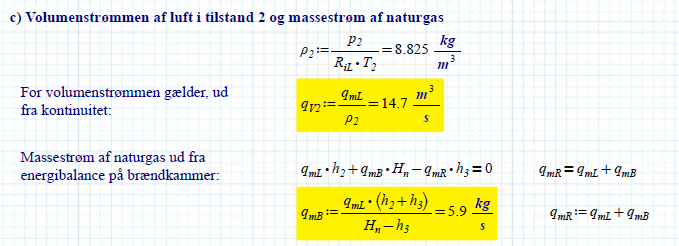

P_aksel_kompressor = nan;

h1 = t1*cp_luft;
h2s = T2s*cp_luft;

P_aksel_kompressor = Kompressor_Koling_isentrop(qm_luft, h1, h2s,P_aksel_kompressor,eta_komp)

Energiligningen opstilles:


$$eq = -\frac{q_{\mathrm{mR}}\,\left(h_{1}-h_{\mathrm{2s}}\right)}{P_{a}}=\eta_{\mathrm{is}}$$

---------------------------------------------------
Hvor P_is er:


$$P_{\mathrm{is}}=q_{\mathrm{mR}}\,\left(h_{\mathrm{2s}}-h_{1}\right)$$

---------------------------------------------------
Der løses for: P_a


$$sol = -\frac{h_{1}\,q_{\mathrm{mR}}-h_{\mathrm{2s}}\,q_{\mathrm{mR}}}{\eta_{\mathrm{is}}}$$

---------------------------------------------------
Resultat og brugte værdier ses i nedenstående skema
            Variabel             Størrelse      Enhed  
    ________________________    ___________    ________

    "Phi isentrop"              52098825.3     "W"     
    "Massestrøm"                130.0          "kg/s"  
    "h1"                        296081.5       "J/kg*K"
    "h2s"                       696841.69      "J/kg*K"
    "P_aksel_kompressor"        65123531.62    "W"     
    "Isentrop virkningsgrad"    0.8            "-"     



$$P\_aksel\_kompressor = 6.512e+7$$


P_aksel_kompressor = P_aksel_kompressor/1e6 % MW

$$P\_aksel\_kompressor = 65.123531621520081534981727600098$$

P_aksel_turbine = nan;

% Turbinen håndterer gas
h3 = t3*cp_gas;
h4 = t4_svarark*cp_gas;
qm_turbine = qm_luft+qmb;


P_aksel_turbine = massestrom_all(P_aksel_turbine,qm_turbine,h3,h4)/1e6

Energiligningen opstilles:


$$eq = \Phi +q_{\mathrm{mR}}\,\left(h_{1}-h_{4}\right)=0$$

---------------------------------------------------
Der løses for: Phi


$$sol = h_{4}\,q_{\mathrm{mR}}-h_{1}\,q_{\mathrm{mR}}$$

---------------------------------------------------
Resultat og brugte værdier ses i nedenstående skema
      Variabel       Størrelse      Enhed 
    ____________    ____________    ______

    "Phi "          107124437.96    "W"   
    "Massestrøm"    135.9           "kg/s"
    "h3"            1612500.0       "J/kg"
    "h4"            824240.71       "J/kg"



$$P\_aksel\_turbine = 107.12443795778565248474478721619$$



% Den afgivne effekt til generatoren bliver
P_generator = P_aksel_turbine - P_aksel_kompressor

$$P\_generator = 42.000906336265570949763059616089$$

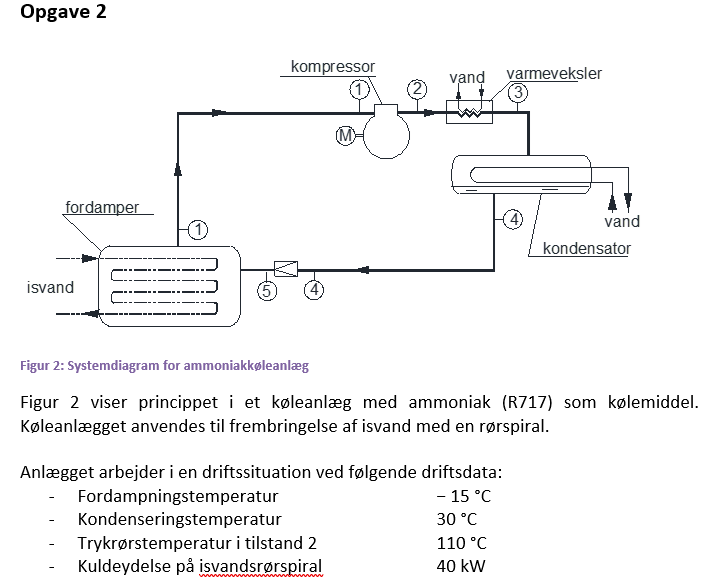

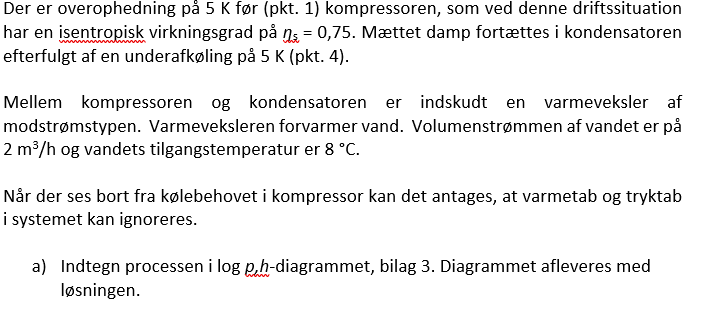

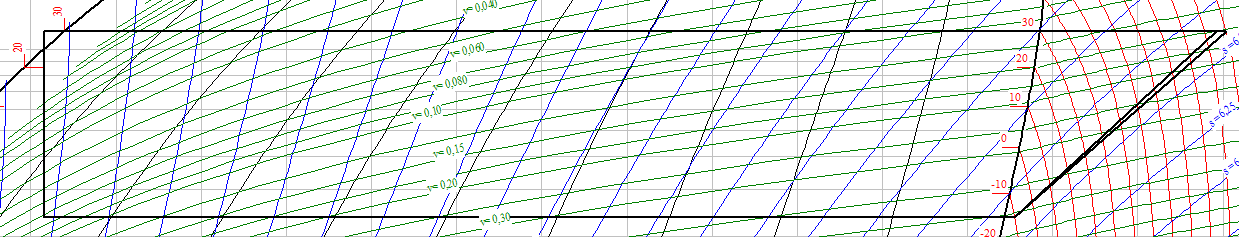

Trykkene kan aflæses i log-ph diagrammer


$$p_0 = 2,354 \text{bar}$$



$$p_k = 11,67 \text{bar}$$


clc; clear;
CP = py.importlib.import_module("CoolProp.CoolProp");

phi0 = 40e3; % kW til W
h1 = 1455.339e3;
h2 = 1703.711e3;
h3 = 315.538e3;
h4 = h3;

qmr = nan;
qmr = massestrom_all(phi0, qmr, h1, h4)

Energiligningen opstilles:


$$eq = \Phi +q_{\mathrm{mR}}\,\left(h_{1}-h_{4}\right)=0$$

---------------------------------------------------
Der løses for: q_mR


$$sol = -\frac{\Phi }{h_{1}-h_{4}}$$

---------------------------------------------------
Resultat og brugte værdier ses i nedenstående skema
      Variabel      Størrelse     Enhed 
    ____________    __________    ______

    "Phi "               40000    "W"   
    "Massestrøm"          0.04    "kg/s"
    "h1"            1.4553e+06    "J/kg"
    "h4"            3.1554e+05    "J/kg"



$$qmr = 0.03509$$

qmr_hr = qmr*3600 % korrekt

$$qmr\_hr = 126.33784318486505071632564067841$$

eta_komp = 0.75;
h2s = 1692.31e3;
phi_komp_afgivet = nan;
P_aksel_komp = nan;

P_aksel_komp = Kompressor_Koling_isentrop(qmr, h1, h2s, P_aksel_komp,eta_komp)

Energiligningen opstilles:


$$eq = -\frac{q_{\mathrm{mR}}\,\left(h_{1}-h_{\mathrm{2s}}\right)}{P_{a}}=\eta_{\mathrm{is}}$$

---------------------------------------------------
Hvor P_is er:


$$P_{\mathrm{is}}=q_{\mathrm{mR}}\,\left(h_{\mathrm{2s}}-h_{1}\right)$$

---------------------------------------------------
Der løses for: P_a


$$sol = -\frac{h_{1}\,q_{\mathrm{mR}}-h_{\mathrm{2s}}\,q_{\mathrm{mR}}}{\eta_{\mathrm{is}}}$$

---------------------------------------------------
Resultat og brugte værdier ses i nedenstående skema
            Variabel            Størrelse     Enhed  
    ________________________    _________    ________

    "Phi isentrop"              8316.22      "W"     
    "Massestrøm"                0.04         "kg/s"  
    "h1"                        1455339.0    "J/kg*K"
    "h2s"                       1692310.0    "J/kg*K"
    "P_aksel_komp"              11088.3      "W"     
    "Isentrop virkningsgrad"    0.75         "-"     



$$P\_aksel\_komp = 11090.0$$


Kompressor_Koling(phi_komp_afgivet, qmr, h1, h2, P_aksel_komp)

Energiligningen opstilles:


$$eq = P_{a}-\Phi_{\mathrm{kt}}+q_{\mathrm{mR}}\,\left(h_{1}-h_{2}\right)=0$$

---------------------------------------------------
Hvor Pa er:


$$P_{a}=\eta_{\mathrm{motor}}\,P_{\mathrm{el}}$$

---------------------------------------------------
Der løses for: Phi_kt


$$sol = P_{a}+q_{\mathrm{mR}}\,\left(h_{1}-h_{2}\right)$$

---------------------------------------------------
Resultat og brugte værdier ses i nedenstående skema
         Variabel         Størrelse     Enhed  
    __________________    _________    ________

    "phi_komp_afgivet"    2371.97      "W"     
    "Massestrøm"          0.04         "kg/s"  
    "h1"                  1455339.0    "J/kg*K"
    "h2"                  1703711.0    "J/kg*K"
    "P_aksel_komp"        11088.3      "W"     



$$ans = 2372.0$$

phi_vv = nan;
h3_vv = 1486e3; % aflæst på diagrammet

phi_vv = massestrom_all(phi_vv,qmr, h2, h3_vv)

Energiligningen opstilles:


$$eq = \Phi +q_{\mathrm{mR}}\,\left(h_{1}-h_{4}\right)=0$$

---------------------------------------------------
Der løses for: Phi


$$sol = h_{4}\,q_{\mathrm{mR}}-h_{1}\,q_{\mathrm{mR}}$$

---------------------------------------------------
Resultat og brugte værdier ses i nedenstående skema
      Variabel      Størrelse    Enhed 
    ____________    _________    ______

    "Phi "          7640.32      "W"   
    "Massestrøm"    0.04         "kg/s"
    "h2"            1703711.0    "J/kg"
    "h3_vv"         1486000.0    "J/kg"



$$phi\_vv = 7640.0$$